# Implementation Structures for IIR and FIR Systems (150 Points)

Dear Students, 

Welcome to Lab 4! In this lab, you will implement IIR and FIR filters using several different structures.  

### **References: **

-  Chapter 6, Section 0 - 5 of "A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall, 2nd Edition".

-  "Week-7 Video-3.mp4" and "Week-7 Video-4.mp4" of EE321 Course. 

-  [https://spinlab.wpi.edu/courses/ece503_2014/week8.html](https://spinlab.wpi.edu/courses/ece503_2014/week8.html)

## IIR Systems **(100 Points)**

#### **Question 1:   **

Name IIR filter implementation structures that you have studied. 

ANS: Direct form Structure, Transformed form Structure, Cascade form Structure and Lattice Structure.

Now, consider the following filter transfer function: 

                                                    $H(z) =\frac{1+\frac{5}{6}z^{-1}+\frac{1}{6}z^{-2} }{1+z^{-1}+\frac{1}{2}z^{-2}}$ .............................................................   (1)

-  What are the $b$ and $a$ coefficients  in (1)? (Find by inspection)

% coeffiencits of transfer function 
b = [1 5/6 1/6];
a = [1 1 0.5]; 

- Obtain the impulse response of the above filter in (1) (user [impz](https://in.mathworks.com/help/signal/ref/impz.html)) 

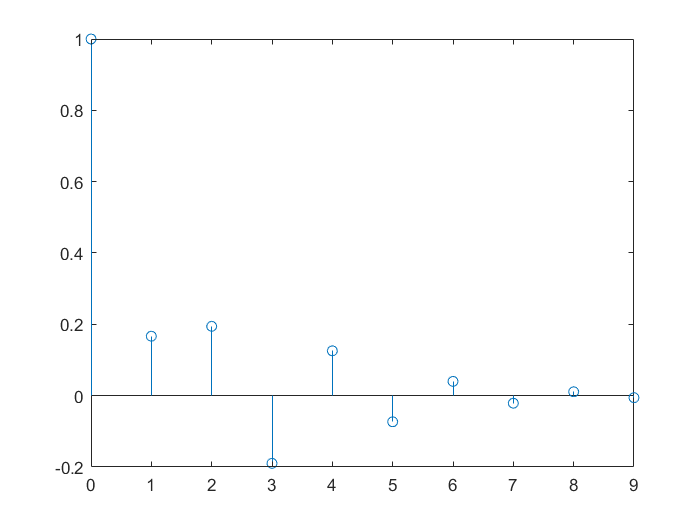

% impulse response
[h,t] = impz(a,b,10);
stem(t,h);

- Obtain the magnitude response of the filter in (1) (use [freqz](https://in.mathworks.com/help/signal/ref/freqz.html))

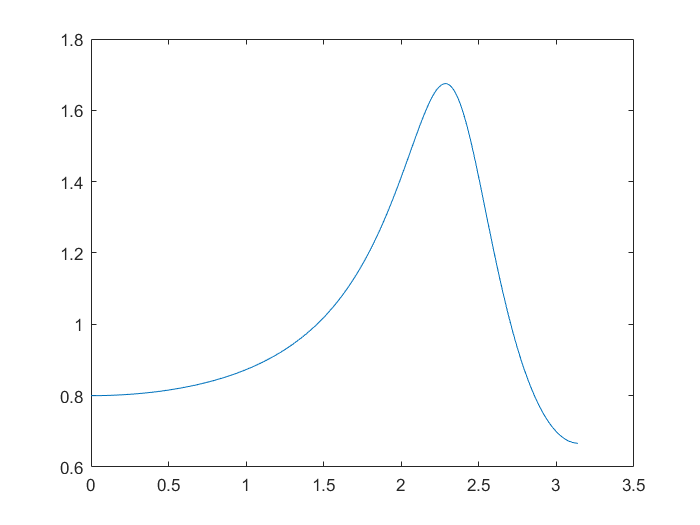

% Magnitude response
[h,w] = freqz(b,a,1024);
plot(w,abs(h));

-  Obtain the pole-zero plot of (1) (use [zplane](https://in.mathworks.com/help/signal/ref/zplane.html)) 

% pole-zero plot
zplane(b,a);

- Is the filter stable?                                                                                                                                                                                                                                                                    

           ANS: Yes the filter is stable, because all the poles lie within the unit circle.

- Why are complex poles appearing in complex-conjugate pairs?

           ANS: The coefficients of the filter are real hence the poles or zeros which are complex are in complex conjugate pairs.

- Why is it an IIR filter? 

           ANS: An IIR filter is an Infinite impulse response filter, this means that the impulse response of the IIR filter is infinitely long. the impulse response of the given filter is also infinitely long because it has poles on location other than 0. hence it is an IIR filter

Now speak and record your voice or music for 5 seconds (see [audiorecorder](https://in.mathworks.com/help/matlab/ref/audiorecorder.html) and[ ](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering)[https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering).](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering).) Assign the recorded sequence to a variable named 

rec = audiorecorder;
disp('Start')

Start


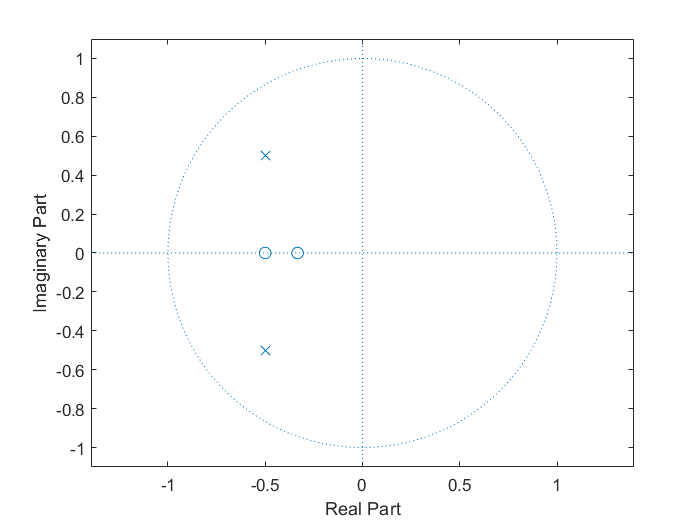

recordblocking(rec, 5);

disp('End');

End


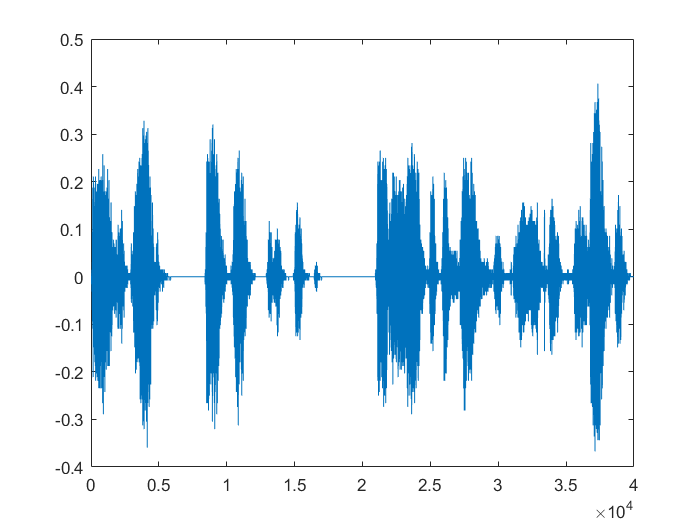

x = getaudiodata(rec);
myRecordedSignal = x;
plot(myRecordedSignal)%plot freq graph

In the following, you will filter $myRecordedSignal$ with the filter in (1) using  different IIR filter structures.

### Direct Form - I Structure:

Now, given, $myRecordedSignal$ signal,  write a code to compute the output using Direct Form - I structure (see the below figure).  

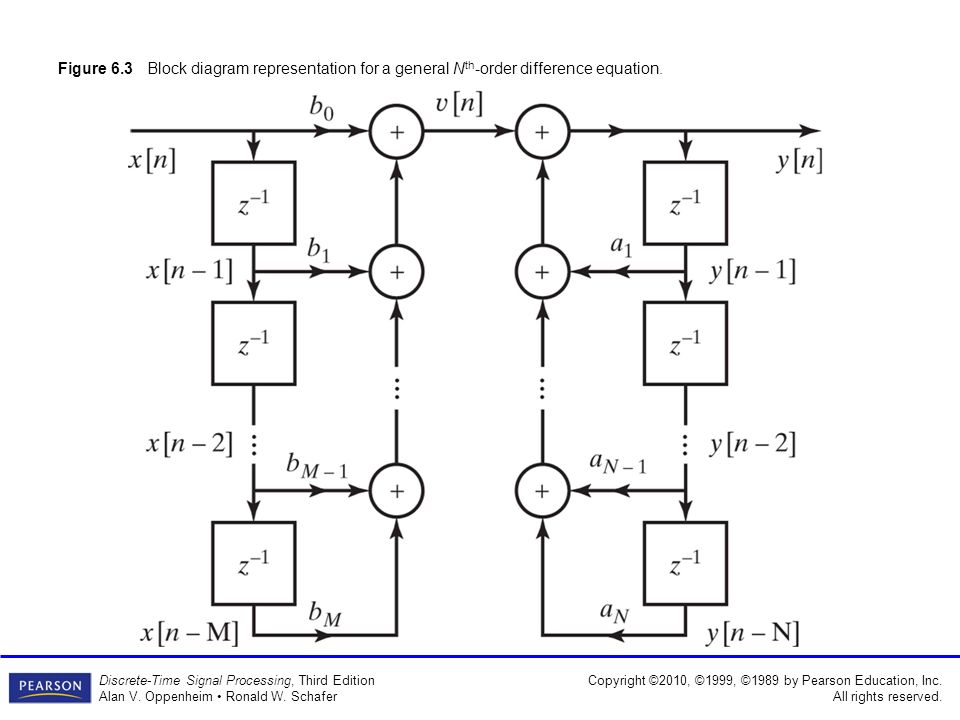

-   Before you code, write the difference equation relation between input sequence, $x[n]$ and output sequence, $y[n]$.          

              ANS (completed for you) :               $y[n] = -y[n-1]-0.5y[n-2]+x[n]+\frac{5}{6}x[n-1]+\frac{1}{6}x[n-2]$                            

% Completed for you. 
y =  zeros(1, length(x)+2); 

for n =  3: length(x)    % Why are we starting at index 3? 
    y(n) = -1*y(n-1)-0.5*y(n-2)+x(n)+(5/6)*x(n-1)+(1/6)*x(n-2);     
end


- In the above code snippet, why are we starting the *for-loop* at index 3? 

            ANS: when n = 0 we need to use the values of y[-2] & y[-1]. but we need to store these values in a matlab array which do not support -ve index. So to overcome that problem we store y[-2] and y[-1] in the index 1 and 2 respectively, hence we are starting our index from 3. index 3 corresponds to 'n = 0'. 

- How many multiplications and delay elements are required for the Direct Form I implementation?

            ANS: In Direct Form I we require 4 delay elements and 4 multiplication elements (as $a_0 =1$ & $b_0 =1$). 

- Now, listen to the original and filtered signal (use [sound](https://in.mathworks.com/help/matlab/ref/sound.html))   

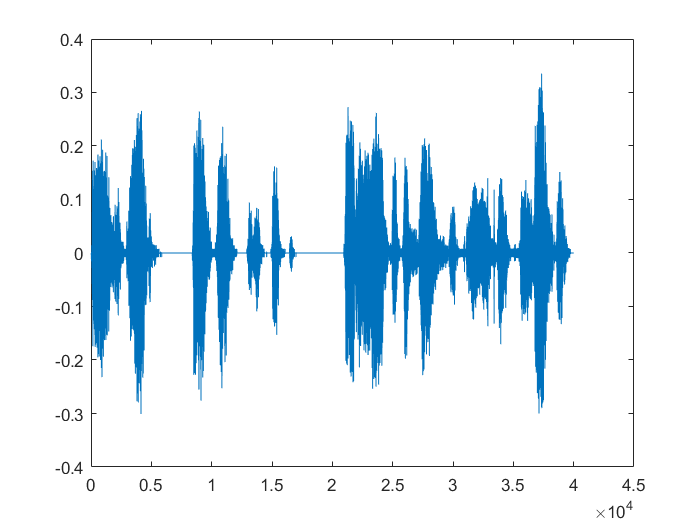

 % play your signals here, Use appropriate sampling frequency
sound(y)
plot(y);

- Now, compute and plot magnitude responses of the original and filtered signals  (Write a function MagnitudeResponse(x, Fs)  so that you can reuse it)

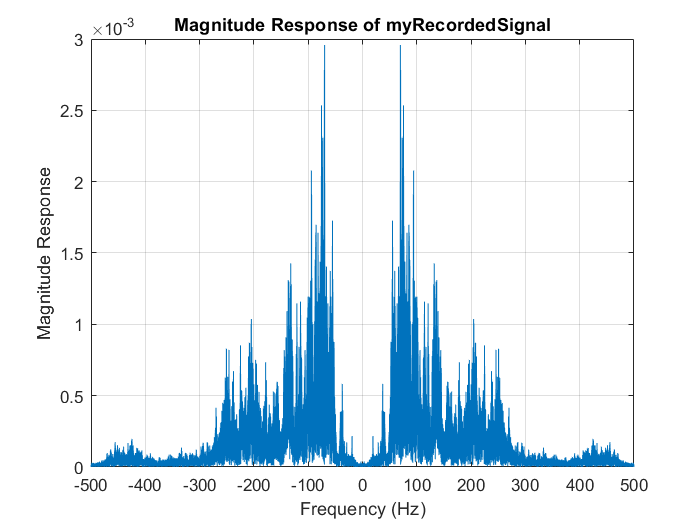

%  MagnitudeResponse(x, Fs, SignalName) % This function needs to be defined at the end of the
%  file (Matlab requires you to do that). A skeleton is provided. 

Fs = 1000;
MagnitudeResponse(x, Fs, 'myRecordedSignal');  

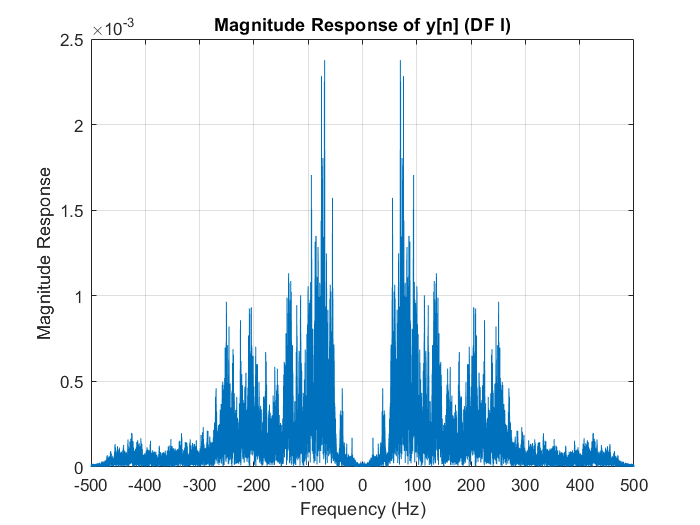

MagnitudeResponse(y, Fs, 'y[n] (DF I)');   

- Write your observations  related to above magnitude responses. 

We observe that for the lower freqency the ampltudes have decreased whereas the amplitudes for higher frequencies have increased. This is due to the bandpass nature of our filter, this filter has lower gain for lower ferquencies, and higher gain for  1 to  2.5 normalized frequency.

### Direct Form - II Structure:

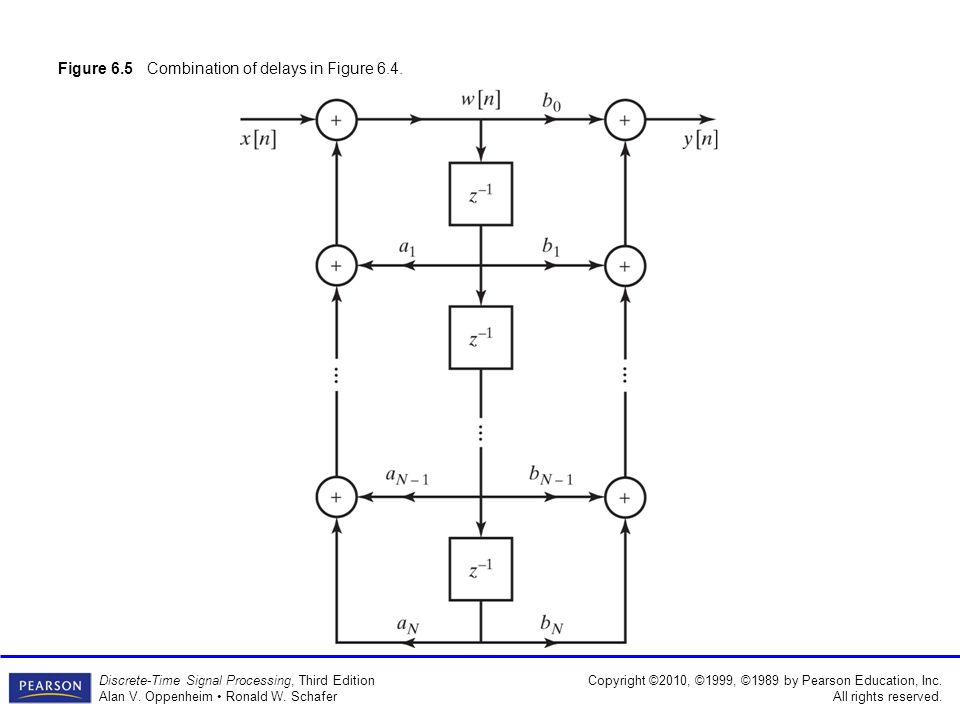

- Before you code, write down difference equations required to implement (1) in Direct Form - II. 

            ANS:  $$$\begin{array}{l}
x\left\lbrack n\right\rbrack \;-w\left\lbrack n-1\right\rbrack -\frac{1}{2}w\left\lbrack n-2\right\rbrack =w\left\lbrack n\right\rbrack \\
w\left\lbrack n\right\rbrack +\frac{5}{6}w\left\lbrack n-1\right\rbrack +\frac{1}{6}w\left\lbrack n-2\right\rbrack =y\left\lbrack n\right\rbrack 
\end{array}$

- How many multiplications and delay elements are required for the Direct Form II implementation?

            ANS:   We require 2 delay elements and 4 multiplication elements in the Direct Form II. 

- Code:

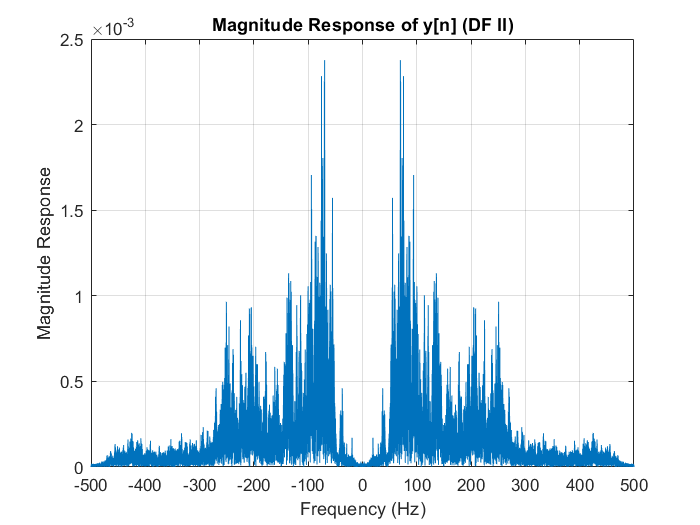

% Write your code here
w =  zeros(1, length(x)+2); 
y =  zeros(1, length(x)+2); 

for n =  3: length(x)    % Why are we starting at index 3? 
    w(n) = x(n) - 0.5*w(n-2) - w(n-1);     
end

for n =  3: length(x)    % Why are we starting at index 3? 
    y(n) = 5*w(n-1)/6 + w(n-2)/6 + w(n);     
end

MagnitudeResponse(y, Fs, 'y[n] (DF II)')

### Cascade Form Structure: 

#### First-Order Sections

-    Implement the filter in (1) in cascade form structure with first-order sections

                -  Write down difference equations required for the implement, here: 

                   
$$\begin{array}{l}
x\left\lbrack n\right\rbrack +0\ldotp 5x\left\lbrack n-1\right\rbrack \;=w_1 \left\lbrack n\right\rbrack \\
w_1 \left\lbrack n\right\rbrack -\left(0\ldotp 5+0\ldotp 5j\right)w_2 \left\lbrack n-1\right\rbrack =w_2 \left\lbrack n\right\rbrack \\
w_2 \left\lbrack n\right\rbrack +0\ldotp 33w_2 \left\lbrack n-1\right\rbrack =w_3 \left\lbrack n\right\rbrack \\
w_3 \left\lbrack n\right\rbrack -\left(0\ldotp 5-0\ldotp 5j\right)y\left\lbrack n-1\right\rbrack =y\left\lbrack n\right\rbrack 
\end{array}$$
    

-   Code:     

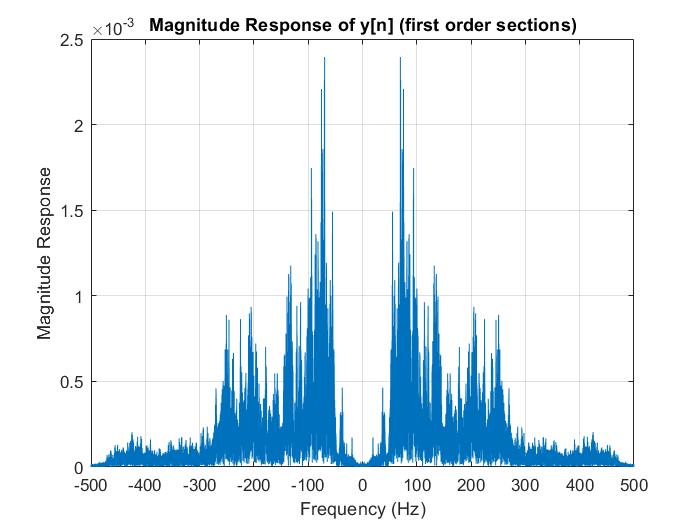

% First-order sections
 % Write your code here
w1 =  zeros(1, length(x)+1);
w2 =  zeros(1, length(x)+1);
w3 =  zeros(1, length(x)+1);
y =  zeros(1, length(x)+1); 

for n =  2: length(x) 
    w1(n) = x(n) + 0.5*x(n-1);
end

for n =  2: length(x)     
    w2(n) = w1(n) - (0.5 + 0.5*1i)*w2(n-1);     
end

for n =  2: length(x)  
    w3(n) = w2(n) + (1/3)*w2(n-1);    
end

for n =  2: length(x)    
    y(n) = w3(n) - (0.5 - 0.5*1i)*y(n-1);     
end

MagnitudeResponse(y, Fs, 'y[n] (first order sections)')

####  Second-Order Sections

-    Implement the filter in (1) in cascade form structure with second-order sections

                -  Write down difference equations required for the implementation, here: 

                   
$$\begin{array}{l}
x\left\lbrack n\right\rbrack \;-w\left\lbrack n-1\right\rbrack -\frac{1}{2}w\left\lbrack n-2\right\rbrack =w\left\lbrack n\right\rbrack \\
w\left\lbrack n\right\rbrack +\frac{5}{6}w\left\lbrack n-1\right\rbrack +\frac{1}{6}w\left\lbrack n-2\right\rbrack =y\left\lbrack n\right\rbrack 
\end{array}$$


-    Code:

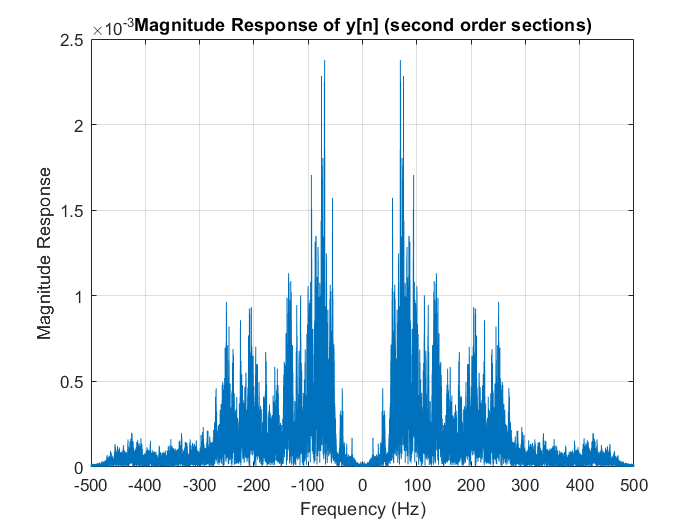

% Second-order sections
% Write your code here
w =  zeros(1, length(x)+2); 
y =  zeros(1, length(x)+2); 

for n =  3: length(x) 
    w(n) = x(n) - 0.5*w(n-2) - w(n-1);     
end

for n =  3: length(x)   
    y(n) = 5*w(n-1)/6 + w(n-2)/6 + w(n);     
end

MagnitudeResponse(y, Fs, 'y[n] (second order sections)')

- Compare your first-order and second order section cascaded implementations, in terms of number of real and complex multiplications, number of memory elements. Why is second-order sections (SOS) preferred? 

            ANS: the number of memory elements required for second order sections is 2 whereas the number of memory elements required in first order section is 4. hence we require a lesser number of memory elements in second order sections. As far as multiplications are considered, we need 4 multiplication in both the cases but in the case of first order sections we require 2 complex multiplications, which are computationally more expensive. second order sections are preffered, because we have only real multiplications and the memory elements required are lesser than first order sections.

### Parallel Form Structures:

- Express the transfer function in (1) to suit the parallel  form implementation

               ANS:  $H(z) = \frac{1}{3} + \frac{\Big( \frac{1}{3} - \frac{i}{6} \Big)}{(1+(0.5 + i0.5)z^{-1})} + \frac{\Big( \frac{1}{3} + \frac{i}{6} \Big)}{(1+(0.5 - i0.5)z^{-1})}$ 

- Write down difference equations required for parallel  form implementation here. 

               ANS:  $w_1[n] = \frac{1}{3} x[n]$

                          
$$w_2[n] = \Big( \frac{1}{3} - \frac{i}{6} \Big)\Big( x[n] - (0.5 + i0.5)y_2[n-1]\Big)$$


                         
$$w_3[n] = \Big( \frac{1}{3} + \frac{i}{6} \Big)\Big( x[n] - (0.5 - i0.5)y_2[n-1]\Big)$$


- Code: 

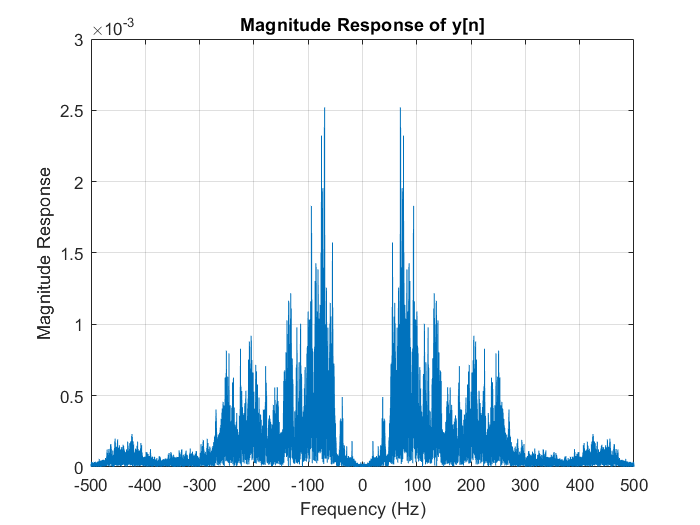


w1 = zeros(1, length(x)+1);
w2 = zeros(1, length(x)+1);
w3 = zeros(1, length(x)+1);
y = zeros(1, length(x)+1);

for n =  2: length(x)  
    
    w1(n) = (1/3)*x(n);
    w2(n) = (1/3 - 1i/6)*(x(n) - (0.5 + 1i*0.5)*w2(n-1));
    w3(n) = (1/3 + 1i/6)*(x(n) - (0.5 - 1i*0.5)*w3(n-1));
    
    y(n) = w1(n) + w2(n) + w3(n);
    
end

MagnitudeResponse(y, Fs, 'y[n]'); 

- How many multiplications and memory elements are required? 

         We require 4 complex multiplications and 1 real multiplications.

         We require 2 memory elements.

### Transposed Form Structures:      

- Draw the transposed form  of your Direct Form  II structure of (1)

          ANS: 

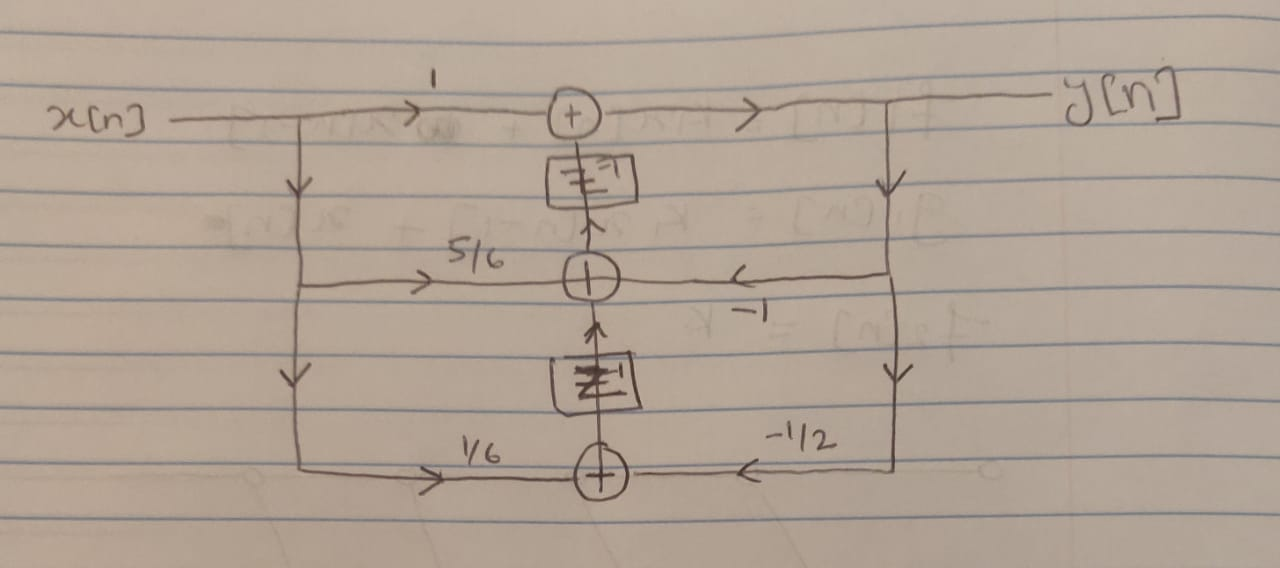

- Write down the corresponding difference equations

            ANS:   $y[n] = -y[n-1]-0.5y[n-2]+x[n]+\frac{5}{6}x[n-1]+\frac{1}{6}x[n-2]$

-  Code

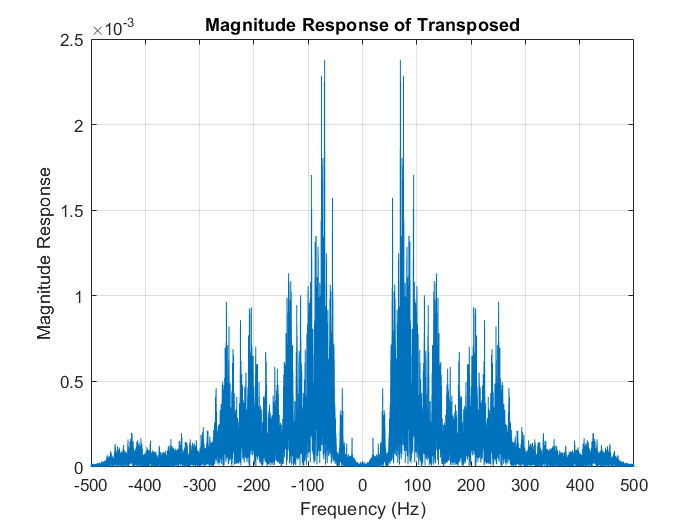

% Write your code here
y =  zeros(1, length(x)+2); 

for n =  3: length(x)    
    y(n) = -1*y(n-1)-0.5*y(n-2)+x(n)+(5/6)*x(n-1)+(1/6)*x(n-2);     
end

MagnitudeResponse(y , Fs , 'Transposed')

### Lattice Form Structures (OPTIONAL)

- Draw the lattice form of (1). To get lattice coefficients, you can use *tf2latc*

- Implement the lattice structure 

% Code here (OPTIONAL)

###  General Questions: 

- (False)  The number of delay elements required for the direct form-I implementation of an IIR filter is strictly greater than that for the direct form -II implementation.  

- (False)The number of multiply and accumulate operations in the direct form - II and transpose forms are the same. 

- (True): In a filter with complex conjugate poles and zeros, second-order-sections are used so that multiplications are always real.    

- (True): In the transposed structures, input values are not stored but intermediate values are stored.  

- (False): Transposed structures require more number of multiplications and memory elements compared to their original counterparts. 

- Write any of your observations here, that we not asked in any of the questions above. 

All the structures used above give the same magnitude response as all of them correspond to the same filter.

in IIR filter realization structures we need lesser Multiplications due to the presence of feedback.

Transposed Form is better as we require lesser number of accumulators.

## FIR Filters **(50 Points)**

- Name different FIR structures that you have studied. 

            ANS: Realization methods for FIR filters are

1) Direct form Structure(full and minimum multiplictions in case of GLP filter) 

2) Cascade form structure

3) Transposition form Structure

In this section, we are interested in two forms only

- Structures for Linear-Phase FIR Systems

- Lattice Structures

### Structures for Linear-Phase FIR Systems

Consider $H(z) = 1+2z^{-1}+3z^{-2}+2z^{-3}+z^{-4}$. 

- Draw the Direct Form structure with a minimum number of multiplications for implementing the $H(z)$ above. 

            ANS 

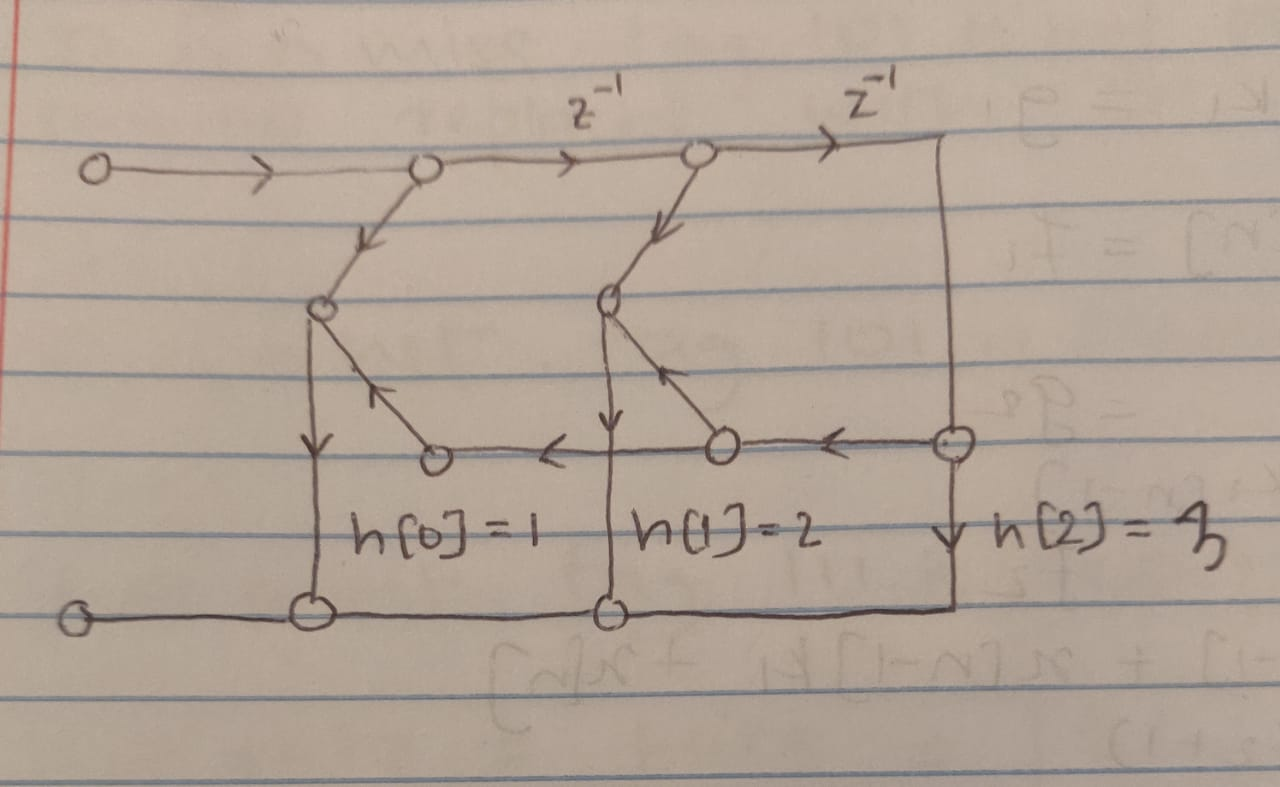. 

- Write down corresponding difference equations

            ANS $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +2x\left\lbrack n-1\right\rbrack +3x\left\lbrack n-2\right\rbrack +2x\left\lbrack n-3\right\rbrack +x\left\lbrack n-4\right\rbrack$

- Code: 

% Write your code here. Use myRecordedSignal as the input for your filter. 

y =  zeros(1, length(x)+5); 

for n =  5 : length(x)   
    y(n) = x(n) + 2*x(n-1) + 3*x(n-2) + 2*x(n-3) + x(n-4);     
end

MagnitudeResponse(y,Fs,'Linear Phase System')

### Lattice Structures

Consider $H(z) = 1+\frac{3}{2}z^{-1}-z^{-2}+\frac{3}{4}z^{-3}+2z^{-4}$. 

- Draw the lattice structure for implementing the $H(z)$ above. 

            ANS:

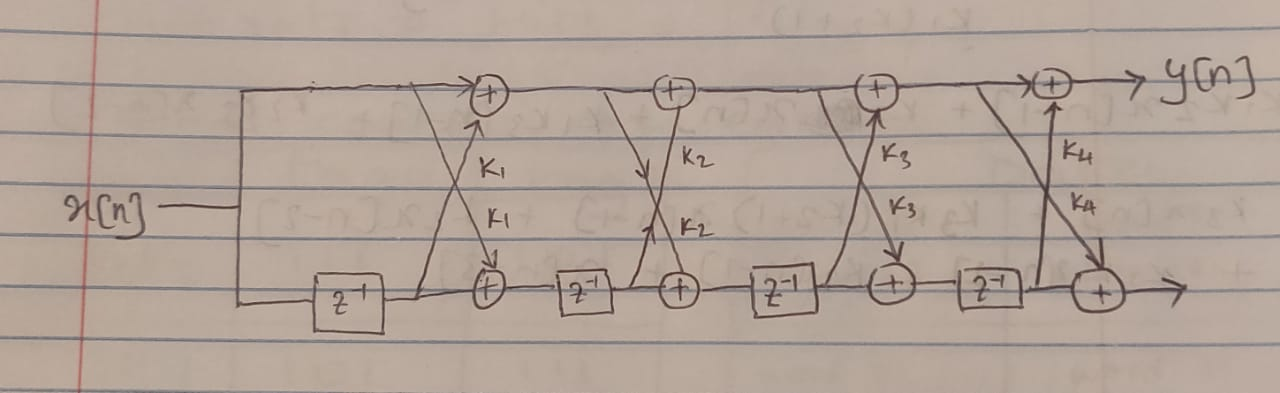 

- Compute lattice coefficients  (manually).            $y[n] = x[n] + (k_4k_3+k_3k_2+k_1k_2+k_1)x[n-1]+(k_1k_2k_3k_4+k_1k_2k_3+k_1k_3k_4+k_1k_3+k_2k_4+k_2)x[n-2] + (k_1k_2k_4+k_2k_3k_4+k_1k_4+k_3)x[n-3] + k_4x[n-4]$

            ANS: The computed Lattice coefficients are: k1 = 2.4, k2 = -0.7619, k3 = 0.75 , k4 = 2. these coeffecients match with the ones computed using tf2latc. 

- Implement the above $H(z)$using the lattice form structure. 

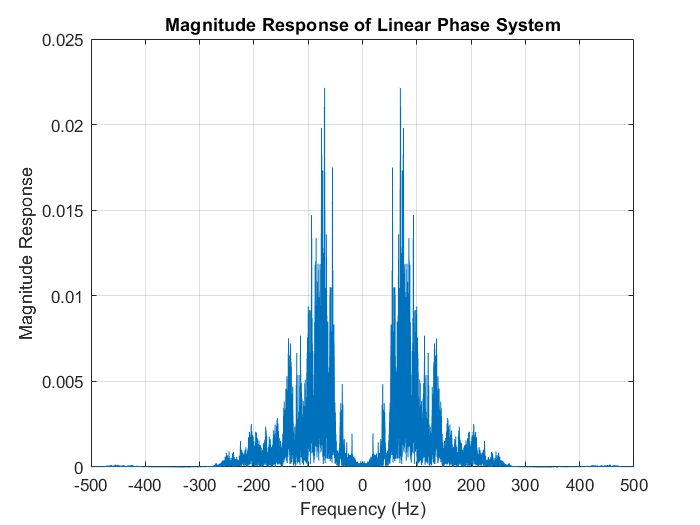

% Write your code here. Use myRecordedSignal as the input for your filter.
k = tf2latc([1 3/2 -1 3/4 2])
x = myRecordedSignal;
f = zeros(5, length(x)+1);
g = zeros(5, length(x)+1);

f(1, :) = [0 x'];
g(1, :) = [0 x'];


for i = 2: length(k)+1
    for n = 2: length(x)+1
        
        f(i, n) = f(i-1, n) + k(i-1)*g(i-1, n-1);
        g(i, n) = k(i-1)*f(i-1, n) + g(i-1, n-1);
        
    end
end

y = f(length(k)+1, :);

MagnitudeResponse(y, Fs, 'y[n]'); 

k =     2.4000
   -0.7619
    0.7500
    2.0000


####  General Questions: 

- Write down observations you have made. 

When we apply Direct form for GLP filters we can use its symmetric property and minimize the number of multiplications.

Lattice Structure is useful because we can represent the whole system can be represented using lattice variables.

## Function Definitions:

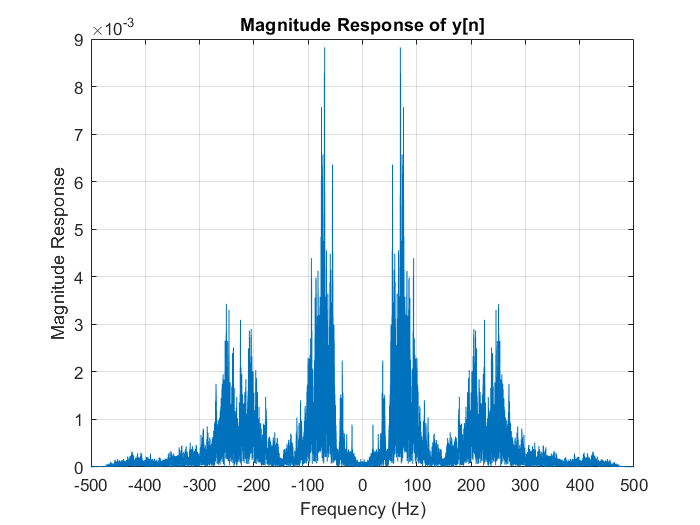

function MagnitudeResponse(x, Fs, SignalName)

% COMPLETE THE CODE HERE TO COMPUTE THE MAGNITUDE RESPONSE OF x

X = fftshift(fft(x))/length(x);
N = length(X);
f = Fs*(-N/2:1:N/2-1)/N;

plot(f,abs(X));
grid on
title(['Magnitude Response of '  SignalName])
xlabel('Frequency (Hz)')
ylabel('Magnitude Response')
end

### Thank you!